**Visualize systems of linear equations**

This shows three planes which intersect at a point, by solving the system of their equations we obtain a solution set which points the coordinate of the intersection of the planes.

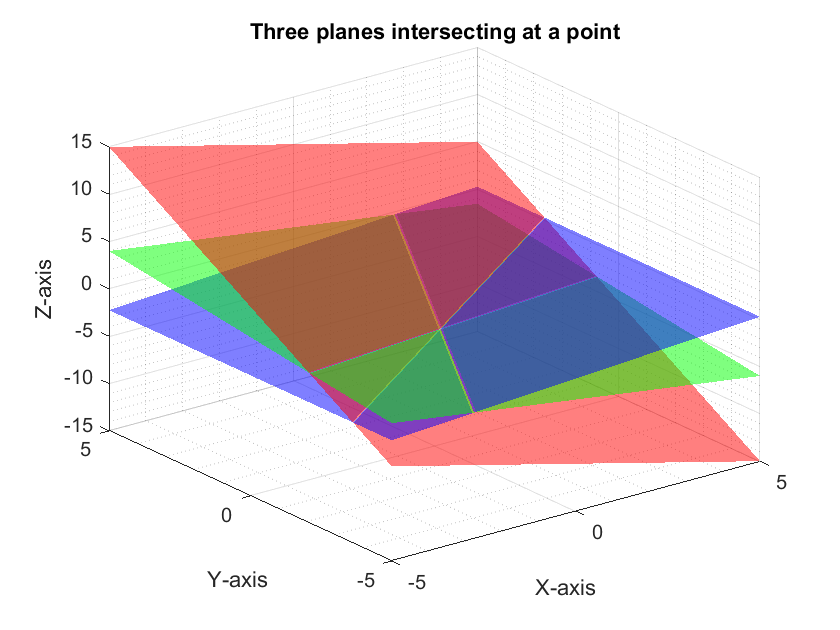

syms x y z
z1 = -x + 2*y; 
figure1 = figure;
axes1 = axes(figure1);
plane1 = fsurf(axes1,z1);
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("Three planes intersecting at a point");
plane1.MeshDensity = 50;
plane1.FaceAlpha = 0.5; % Define opacity
grid on; grid minor;
set(plane1,'FaceColor',[1 0 0]) % Sets the color to red
plane1.EdgeColor = 'none';
hold on

z2 = (1/4)*y - 1;
plane2 = fsurf(z2);
plane2.MeshDensity = 50;
plane2.FaceAlpha = 0.5; % Define opacity
set(plane2,'FaceColor','blue') % Sets the color to red
plane2.EdgeColor = 'none';

z2 = -1 - (5/9)*x + (4/9)*y;
plane2 = fsurf(z2);
plane2.MeshDensity = 50;
plane2.FaceAlpha = 0.5; % Define opacity
set(plane2,'FaceColor','green') % Sets the color to red
plane2.EdgeColor = 'none';

## Solve systems of linear equations

% Define the symbolic variables
syms x y

% Define the system of linear equations
f = 2*x + y == 5

$$f = 2\,x+y=5$$

g = x - y == 1

$$g = x-y=1$$

eqns = [f, g];

% Solve the system of linear equations
sol = solve(eqns, [x, y]);

sol.x

$$ans = 2$$

sol.y

$$ans = 1$$

## Reduced row echelon forms

A = [1 -5 4 0 0;0 1 0 1 0;0 0 3 0 0;0 0 0 2 0];

% The reduced row echelon form
rref(A)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
